%1.1
syms x
A = x^5+4*x^4-2*x^3-14*x^2-3*x-18

$$A = x^{5}+4\,x^{4}-2\,x^{3}-14\,x^{2}-3\,x-18$$

disp(factor(A))

$$\left(\begin{array}{cccc} x-2 & x^{2}+1 & x+3 & x+3 \end{array}\right)$$

%1.2
clear
syms x y
A = x^3+x^2*y+x^2-2*x*y^2+x*y-2*y^2

$$A = x^{3}+x^{2}\,y+x^{2}-2\,x\,y^{2}+x\,y-2\,y^{2}$$

disp(factor(A))

$$\left(\begin{array}{ccc} x+1 & x-y & x+2\,y \end{array}\right)$$

%2.1
clear
syms x
y = x*exp(-x);
disp(limit(y,inf))

$$ans = 0$$

%2.2
clear
syms x
y = (tan(x))^(tan(2*x));
disp(limit(y,x,pi/4))

$${\mathrm{e}}^{-1}$$

%2.3
clear
syms x
y = atan(1/(1-x));
disp(limit(y,x,1,"right"))

$$-\frac{\pi }{2}$$

%2.4
clear
syms x
y = (7*x^3+x^2-1)/(5*x^2+2*x+1);
disp(limit(y,inf))

$$\infty$$

%2.5
clear
syms x h
y =((x+h)^(1/2)-x^(1/2))/h;
disp(limit(y,h,0))

$$\frac{1}{2\,\sqrt{x}}$$

%3.1
clear
syms x
y = atan(x)/2-x/(2*(1+x^2)^2);
disp(simplify(diff(y)))

$$\frac{x^{2}\,\left(x^{2}+5\right)}{2\,{\left(x^{2}+1\right)}^{3}}$$

%3.2
clear
syms x
y = 3*x^4-14*x^3+12*x^2+24*x+6;
disp(diff(y))

$$12\,x^{3}-42\,x^{2}+24\,x+24$$

%3.3
clear
syms x
y = (sin(3*x)-cos(3*x))^2;
disp(simplify(diff(y)))

$$-6\,\cos\left(6\,x\right)$$

%3.4
clear
syms x
y = log(x^2+2)/2+(2-x)/(4*(x^2+2))-1/(4*2^(1/2))*atan(x/2^(1/2));
disp(simplify(diff(y)))

$$\frac{x^{3}+x-1}{{\left(x^{2}+2\right)}^{2}}$$

%3.5
clear
syms x
y = 1/6*log((x-3)/(x+3));
disp(simplify(diff(y)))

$$\frac{1}{x^{2}-9}$$

%4.1
clear
syms x
y = (1-x^2)^(1/2)/x^2;
disp(int(y))

$$ans = -\mathrm{asin}\left(x\right)-\frac{\sqrt{1-x^{2}}}{x}$$

%4.2
clear
syms x
y = 1/(sin(x))^3;
disp(int(y))

$$\frac{\log\left(\tan\left(\frac{x}{2}\right)\right)}{2}-\frac{\cos\left(x\right)}{2\,{\sin\left(x\right)}^{2}}$$

%4.3
clear
syms x
y = (sin(2*x)+1)^(1/7)*cos(2*x);
disp(int(y))

$$\frac{7\,{\left(\sin\left(2\,x\right)+1\right)}^{8/7}}{16}$$

%4.4
clear
syms x
y = 15*(x+3)^(1/2)/((x+3)^2*(x)^(1/2));
disp(int(y,1/8,1))

$$3$$

%4.5
clear
syms x
y = 1/(1+x^2);
disp(int(y,0,+inf))

$$\frac{\pi }{2}$$

%4.6
clear
syms x
y = 1/(x^2-1);
disp(int(y,-2,2))

$$\mathrm{NaN}$$

%4.7
clear
syms x
y = log(sin(x));
disp(int(y,0,pi/2))

$$-\frac{\pi \,\log\left(2\right)}{2}$$

%5.1
clear
syms k
disp(symsum(1/k^2,1,inf))

$$\frac{\pi^{2}}{6}$$

%5.2
clear
syms n
disp(symsum((-1)^((n^2+n)/2)*n/2^n,1,inf))

$$\sum_{n=1}^{\infty }\frac{{\left(-1\right)}^{\frac{n^{2}}{2}+\frac{n}{2}}\,n}{2^{n}}$$

%5.3
clear
syms k x
disp(symsum(x^(k),k,0,inf))

$$\left\{ \begin{array}{cl} \infty & \text{ if }1\leq x\\ -\frac{1}{x-1} & \text{ if }\left|x\right|<1 \end{array}\right.$$

%5.4
clear
syms k x
disp(symsum((3-x)^(2*k)/k^(1/2),k,0,inf))

$$\sum_{k=0}^{\infty }\frac{{\left(x-3\right)}^{2\,k}}{\sqrt{k}}$$

%5.5
clear
syms k x
disp(symsum(1/(x-k)^3,k,-inf,inf))

$$\left\{ \begin{array}{cl} \frac{\psi^{\prime \prime }(-x)}{2}-\frac{1}{x^{3}}-\frac{\psi^{\prime \prime }(x)}{2} & \text{ if }x\notin \mathbb{Z} \end{array}\right.$$

%6.1
clear
syms x
y1 = exp(x);
taylor(y1,x,"Order", 5)

$$ans = \frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$


%6.2
y2 = log(2*x-1);
taylor(y2,x,1,"Order", 3)

$$ans = 2\,x-2\,{\left(x-1\right)}^{2}-2$$


%6.3
y3 = (sin(x))^2;
taylor(y3,x,"Order", 10)

$$ans = -\frac{x^{8}}{315}+\frac{2\,x^{6}}{45}-\frac{x^{4}}{3}+x^{2}$$

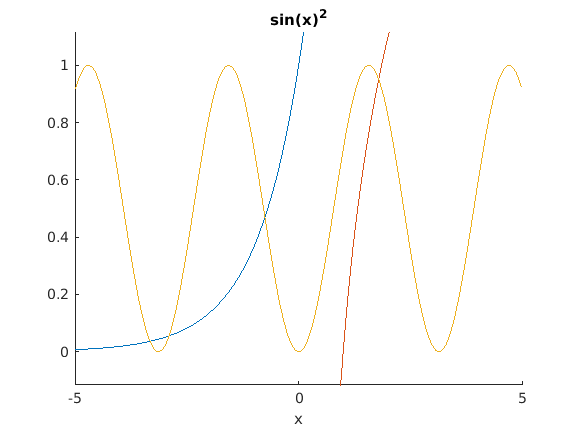


hold on
ezplot(y1, -5, 5);
ezplot(y2, -5, 5);
ezplot(y3, -5, 5);
hold off

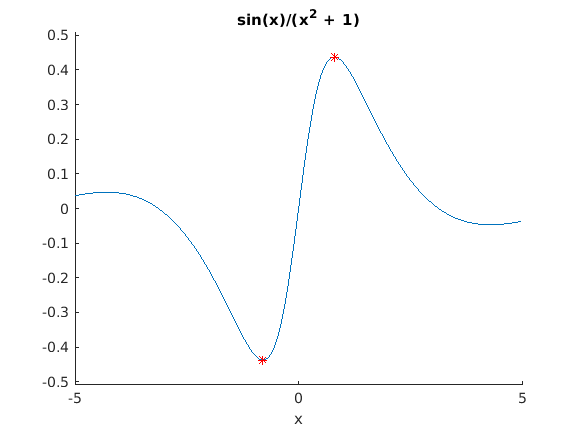

Unrecognized function or variable 'y'.

Error in ezplot>ezplot1 (line 447)
            xrange = [xrange eval(fig)];

Error in ezplot (line 153)
                [hp, cax] = ezplot1(cax, f{1}, vars, labels, args{:});

Error in sym/ezplot (line 91

%7
clear
syms x
f = exp(1/(1-x^2))/(1+x^2);
hold on
ezplot(f)
k = limit(f/x, inf)
b = limit(f-k*x, inf)
y = k*x+b
ezplot(y)
f1=diff(f);
a = solve(f1)
for i=1:length(a)
    plot(a(i),subs(f,x,a(i)),".","MarkerSize", 10,"color","r");
end
f2=diff(f1);
b = solve(f2)
for i=1:length(b)
    plot(b(i),subs(f,x,b(i)),".","MarkerSize", 10,"color","g");
end
hold off

%8
clear
syms x
f = sin(x)/(x^2+1);
hold on
ezplot(f,[-5 5])
y1 = matlabFunction(f);
y2 = matlabFunction(-f);
[min_x1, min_y1] = fminbnd(y1,-5,5)

min_x1 = -0.7980

min_y1 = -0.4374

[min_x2, min_y2] = fminbnd(y2,-5,5)

min_x2 = 0.7980

min_y2 = -0.4374

plot(min_x1, min_y1,'r*');
plot(min_x2, -min_y2,'r*');
hold off

%9
clear
syms t u
x = t*cos(u)*cos(u);
y = t^2*cos(u)*sin(u);
z = t^3*sin(u);
x1 = diff(x,u);
x2 = diff(x1,u);
x3 = diff(x2,u);
y1 = diff(y,u);
y2 = diff(y1,u);
y3 = diff(y2,u);
z1 = diff(z,u);
z2 = diff(z1,u);
z3 = diff(z2,u);
k = (((y1*z2-y2*z1)^2+(z1*x2-z2*x1)^2+(x1*y2-x2*y1)^2)/(x1^2+y^2+z^2)^3)^(1/2);
disp(k)
K = det([x1 y1 z1; x2 y2 z2; x3 y3 z3])/k^2
disp(K)

$$\begin{array}{l} \sqrt{\frac{{\left(4\,t^{5}\,{\cos\left(u\right)}^{2}\,\sin\left(u\right)-t^{3}\,\sin\left(u\right)\,\sigma_{1}\right)}^{2}+{\left(\sigma_{1}\,\sigma_{2}+8\,t^{3}\,{\cos\left(u\right)}^{2}\,{\sin\left(u\right)}^{2}\right)}^{2}+{\left(2\,t^{4}\,\cos\left(u\right)\,{\sin\left(u\right)}^{2}+t^{3}\,\cos\left(u\right)\,\sigma_{2}\right)}^{2}}{{\left(t^{6}\,{\sin\left(u\right)}^{2}+t^{4}\,{\cos\left(u\right)}^{2}\,{\sin\left(u\right)}^{2}+4\,t^{2}\,{\cos\left(u\right)}^{2}\,{\sin\left(u\right)}^{2}\right)}^{3}}}\\ \mathrm{where}\\ \sigma_{1}=t^{2}\,{\cos\left(u\right)}^{2}-t^{2}\,{\sin\left(u\right)}^{2}\\ \sigma_{2}=2\,t\,{\cos\left(u\right)}^{2}-2\,t\,{\sin\left(u\right)}^{2} \end{array}$$